 zeros - 创建全零数组
    此 MATLAB 函数 返回标量 0。

    X = zeros
    X = zeros(n)
    X = zeros(sz1,...,szN)
    X = zeros(sz)

    X = zeros(___,typename)
    X = zeros(___,'like',p)

    See also <a href="D:\SoftWare\Matlab\help\matlab\ref\eye.html">eye</a>, <a href="D:\SoftWare\Matlab\help\matlab\ref\ones.html">ones</a>, <a href="D:\SoftWare\Matlab\help\matlab\ref\rand.html">rand</a>, <a href="D:\SoftWare\Matlab\help\matlab\ref\complex.html">complex</a>, <a href="D:\SoftWare\Matlab\help\matlab\ref\false.html">false</a>, <a href="D:\SoftWare\Matlab\help\matlab\ref\size.html">size</a>

    zeros 的文档
    名为 zeros 的其他函数



/W0001
/W0002
/W0003
/W0004
/W0005
/W0006
/W0007
/W0008
/W0009
/W0010
/W0011
/W0012
/W0013
/W0014
/W0015


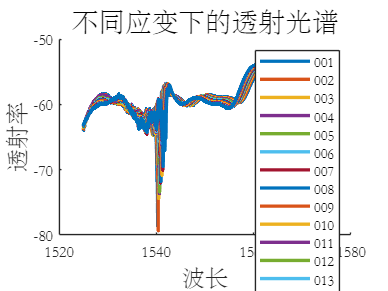

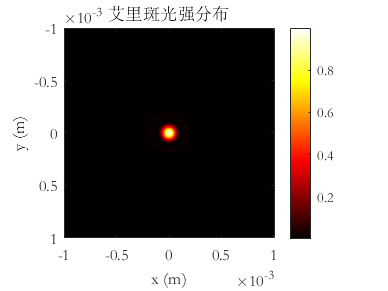

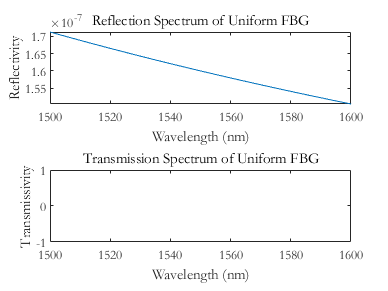

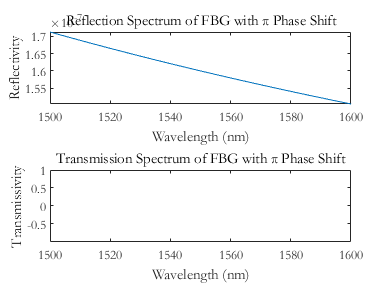

错误使用 plot
向量长度必须相同。

function FBG_TransferMatix(n_eff,L,lambda_Brag)
    
    %-------------变量定义-------------------------------
     
        % n_eff ----------------光栅有效折射率
        % L     ----------------光栅长度
        % lambda_Brag ----------光栅中心波长
        % kappa ----------------光波模式互耦合系数
        % delta ----------------模间失谐量
     
    %----------------------------------------------------
    disp('输入的参数如下');
    disp('光栅有效折射率为：');disp(n_eff);
    disp('布拉格光栅的中心波长为');disp(lambda_Brag);
    disp('布拉格光栅的长度为：');disp(L)
    lambda=1e-9*linspace(1308,1312,500);
    kappa_L=5;
    kappa=kappa_L/L;%交流耦合系数
    F=[1 0;0 1];
    for num=1:500
        f=tansmit_fiber(L,kappa,num,n_eff,lambda,lambda_Brag);
        f=f*F;
        r3(num)=f(2,1)/f(1,1);
        R3(num)=(abs(-r3(num)))^2;%反射率
    end
    subplot(2,1,1)
    plot(lambda*1e9,R3,'r');
    hold on
    subplot(2,1,2)
    plot(lambda*1e9,1-R3,'b')
    hold on
end
�